% Read file

% Baseline property for comparison:
material = [10, 30, 50];
turns = 20;
f_ratio = 2;
save_data = [];

for i = 1:3

    filename = strcat('00',num2str(material(i)),'_',num2str(turns),'turn_F',num2str(f_ratio),'_5.5V_1Hz.csv');

    % filename = '0050_20turn_F2_5.5V_1Hz.csv';

    raw_data = readtable(filename,'Delimiter',',');

    % Take care of header chunk
    raw_time = raw_data{:,"Var1"};
    [row, col] = find(isnan(raw_time));

    if ~isempty(row)
        % double check to make sure nan is from the header instead of data
        if (row(end) - row(1) + 1) == length(row)

            raw_data = raw_data(row(end)+1:end,:); % clip header
        end
    end
    raw_data(end,:) = [];   % get rid of last line in case of incomplete data log


For debugging purposes

    % filePattern = fullfile(pwd, '*.csv'); % Change to whatever pattern you need.
    % theFiles = dir(filePattern);
    %
    % save_data = [];
    %
    % for k = 1 : length(theFiles)
    %     baseFileName = theFiles(k).name;
    %
    %     if length(baseFileName) > 27
    %         ring = 1;
    %     else
    %         ring = 0;
    %     end
    %     material = str2num(baseFileName(3:4));
    %     turn = str2num(baseFileName(6:7));
    %     f_ratio = str2num(baseFileName(14));
    %
    %     if baseFileName(16) == '0'
    %         voltage = 0;
    %     else
    %         voltage = str2num(baseFileName(16:18));
    %     end
    %
    %
    %     raw_data = readtable(baseFileName,'Delimiter',',');
    %
    %     % Take care of header chunk
    %     raw_time = raw_data{:,"Var1"};
    %     [row, col] = find(isnan(raw_time));
    %
    %     if ~isempty(row)
    %         % double check to make sure nan is from the header instead of data
    %         if (row(end) - row(1) + 1) == length(row)
    %             raw_data = raw_data(row(end)+1:end,:); % clip header
    %         end
    %     end
    %     raw_data(end,:) = [];   % get rid of last line in case of incomplete data log
    %


    % Raw time & data
    time = raw_data{:,'Var1'}./1000; % in seconds
    data = raw_data{:,'Var2'};

    % Show raw data plot
    figure;
    plot(time, data)

    time_difference = time(2:end) - time(1:end-1);
    ts = mean(time_difference);
    std_ts = std(time_difference);

    fs = 1/ts;

    rs_time = time(1):ts:time(end);

    rs_data = interp1(time,data,rs_time,'spline');

    figure;
    plot(rs_time,rs_data)

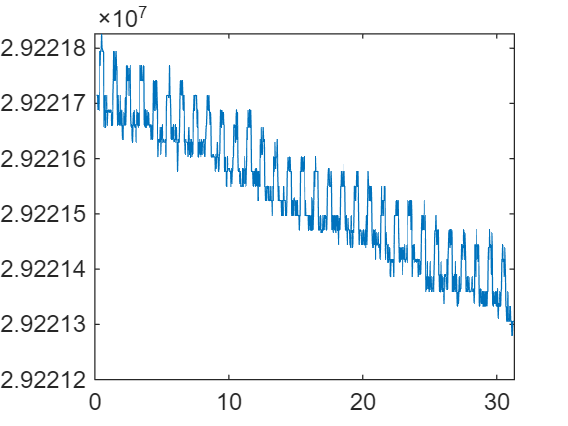

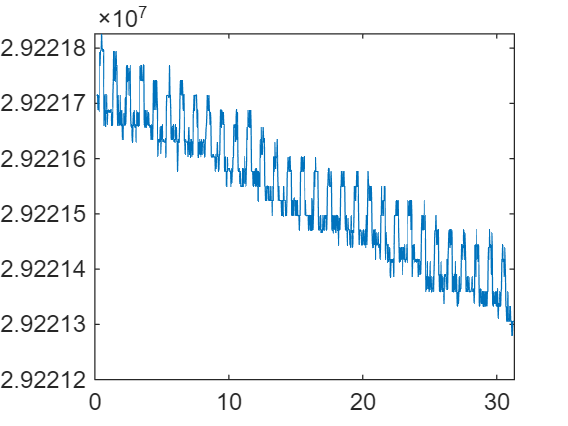

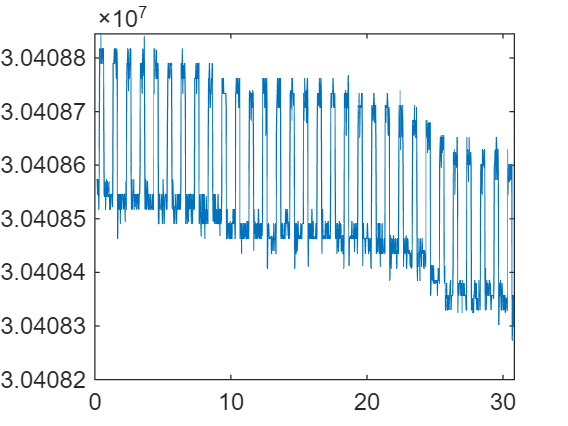

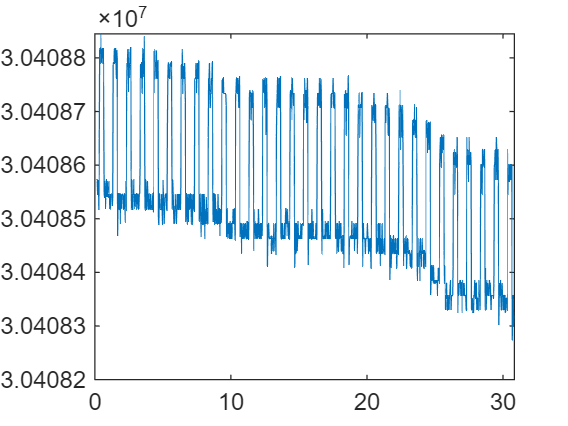

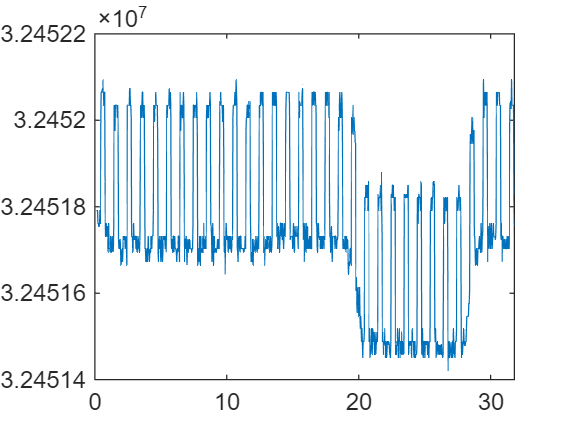

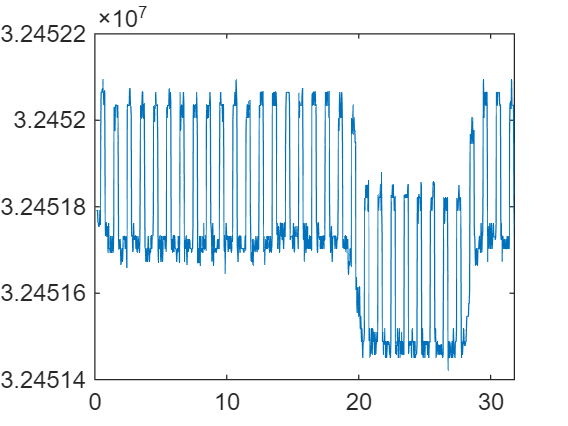

    % Low pass


    % lp_data = filter(lp,rs_data);
    % figure;
    % plot(rs_time,lp_data)





    %%%%%
    % cutoff_freq = 8;    % Cutoff frequency in Hz
    % filter_order = 4;    % Filter order (adjust as needed)
    %
    % % lpf = designfilt('lowpassiir', ...
    % %     'FilterOrder', filter_order, ...
    % %     'HalfPowerFrequency', cutoff_freq, ...
    % %     'SampleRate', fs, ...
    % %     'DesignMethod', 'butter');
    %
    % [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
    % lp_data= filtfilt(b, a, rs_data);
    %
    % figure;
    % plot(rs_time, lp_data)

    % High pass to try to remove baseline

    cutoff_freq = 0.5;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
    hp_data= filtfilt(b, a, rs_data);

    figure;
    plot(rs_time, hp_data)

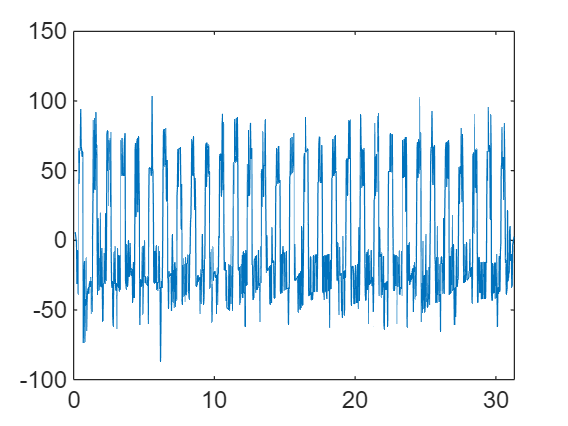

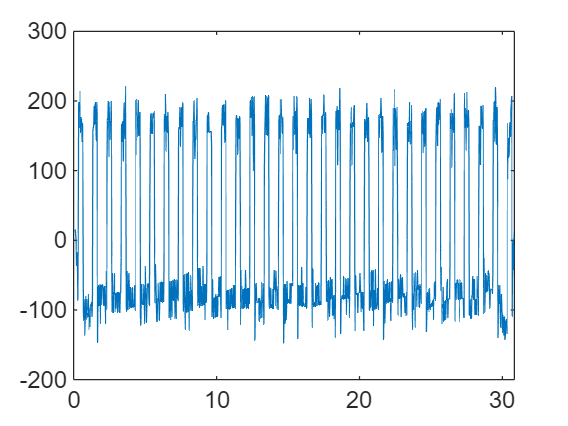

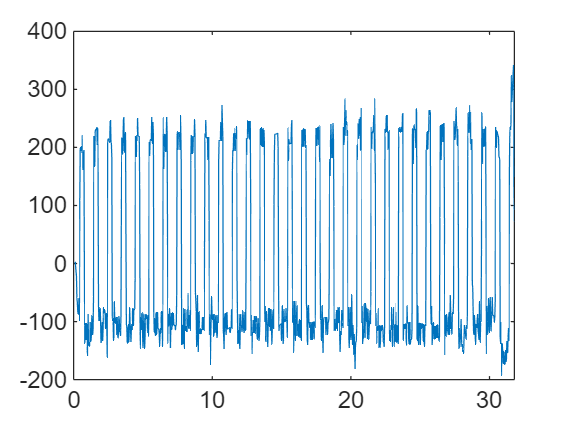

    %% zero passing


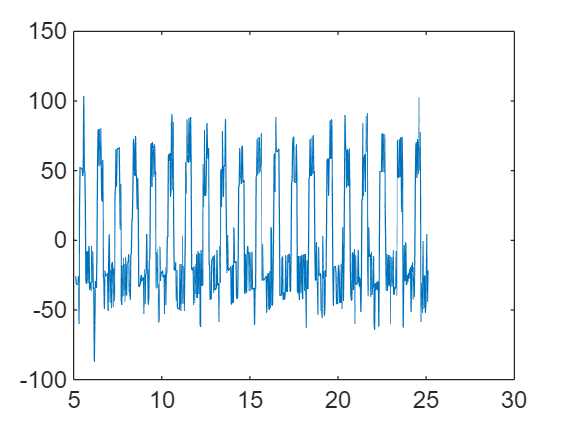

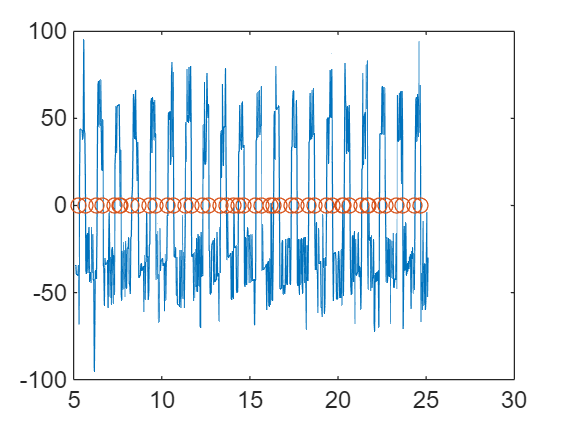

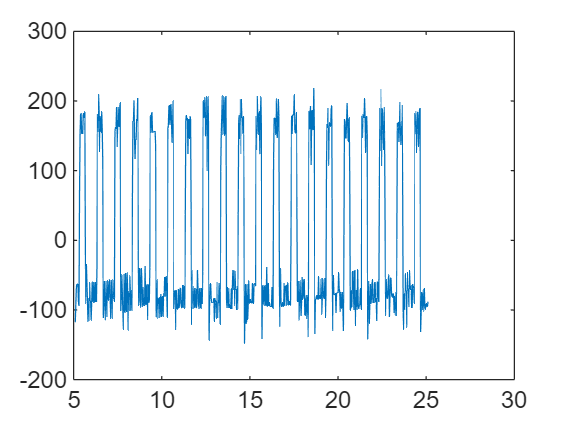

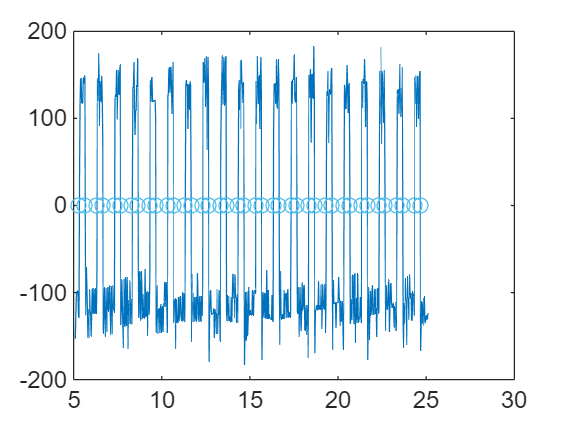

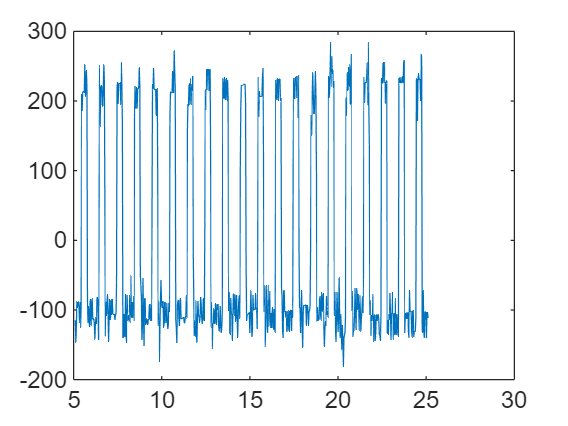

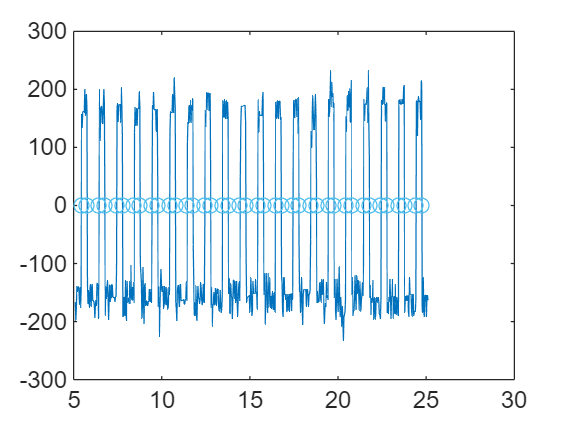

    % clip data

    clip_data = hp_data(ceil(5*fs):ceil(25*fs));
    clip_time = rs_time(ceil(5*fs):ceil(25*fs));

    figure;
    plot(clip_time, clip_data)

    max_data = max(clip_data);
    min_data = min(clip_data);

    p2p_data = max_data - min_data;

    % RMS
    shift_data = clip_data - min_data;
    rms_data = sqrt(mean(shift_data.^2));

    avg_data = clip_data - min_data - p2p_data./2;

    data_prod = avg_data(1:end-1) .* avg_data(2:end);

    zero_crossing = find(data_prod < 0);

    avg_integral = [];

    for m = 1:length(zero_crossing)-1
        time_region = clip_time(zero_crossing(m):zero_crossing(m+1));
        data_region = avg_data(zero_crossing(m):zero_crossing(m+1));
        avg_integral(m) = trapz(time_region, data_region)./(time_region(end) - time_region(1));
    end

    pos_integral = find(avg_integral > 0);
    neg_integral = find(avg_integral < 0);

    pos_mag = mean(avg_integral(pos_integral));
    neg_mag = mean(avg_integral(neg_integral));
    
    
    figure;
    plot(clip_time,avg_data)
    hold on
    plot(clip_time(zero_crossing),zeros(length(zero_crossing)),'o')
    hold off
    magnitude = pos_mag - neg_mag;

    data2save = [material(i),rms_data,magnitude]
    save_data = [save_data;data2save];
end

data2save =    10.0000   96.7107   73.1366


data2save =    30.0000  188.8969  230.8575


data2save =    50.0000  237.2031  303.5361


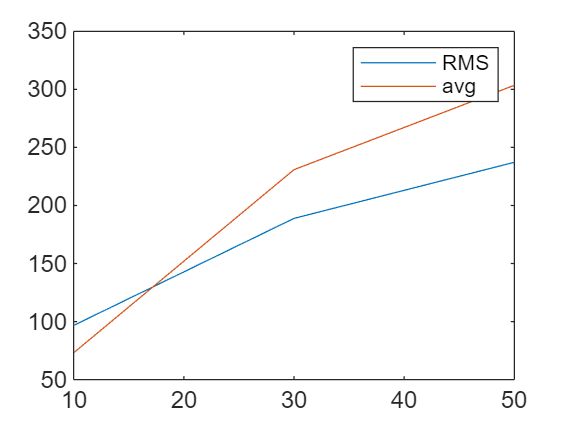

plot(save_data(:,1),save_data(:,2));
hold on
plot(save_data(:,1),save_data(:,3));
hold off
legend('RMS','avg')

% Extract on/off magnitude

